# CÁLCULO NUMÉRICO 1

# PRÁCTICA 1 · TEMA 2 · RAICES DE FUNCIONES 

GRUPO:  **GRUPO 4 **

NOMBRES: 

**JUAN CANO **

**DAVID MARÍN **

**PABLO MENDIETA **

**DAVID MORENO**

FECHA: **18 / 02 / 24**

## P01_T02_P01 · Método de la bisección 

### Respuesta:

**a) **Función adjuntada: `[xs, i] = biseccion(y,a,b,ermax)`

**b) **

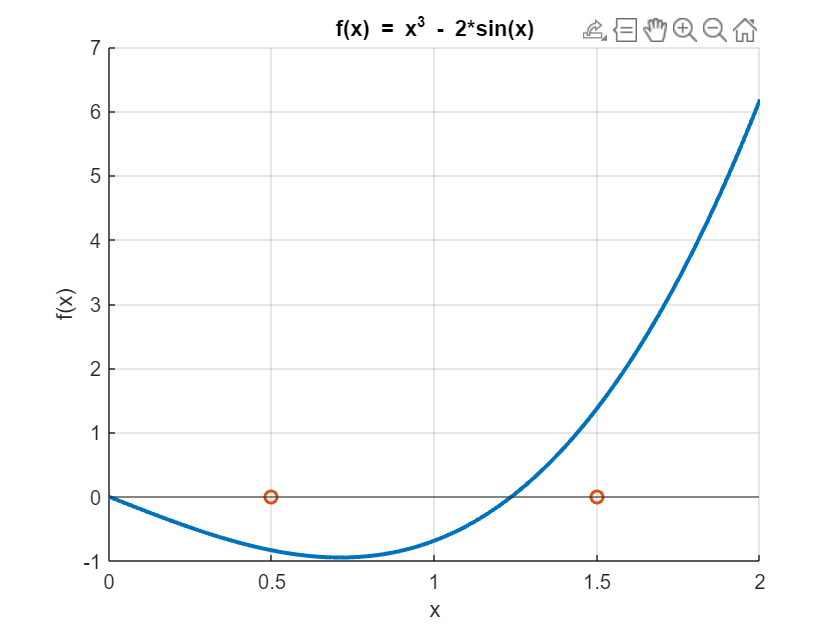

clc, clear, clf

y = @(x) x.^3 - 2*sin(x);
x = linspace(0, 2, 100); % Dibujamos para valores positivos.

% Gráfica
hold on 
yline(0)
ys = y(x);
plot(x, ys, 'LineWidth', 2);
title('f(x) = x^3 - 2*sin(x)')
xlabel('x')
ylabel('f(x)')
x_punto = [0.5, 1.5];
y_punto = [0,0];
plot(x_punto, y_punto, 'o', 'LineWidth', 1.5);
grid on 
hold off

% Valores del intervalo
a = 0.5;
b = 1.5;

ermax = 10e-5;

[xs, i] = biseccion(y,a,b,ermax);
fprintf('Solucion método Bisección: %.5f', xs);

Solucion método Bisección: 1.23615

fprintf('Número de iteraciones necesarias: %d', i);

Número de iteraciones necesarias: 14

solMatlab = fzero(y,b);
error_relativo = abs(xs(end) - solMatlab) / abs(solMatlab) * 100;
fprintf('El error entre la solución de Matlab y de RegulaFalsi es: %.6f %%', error_relativo)

El error entre la solución de Matlab y de RegulaFalsi es: 0.003147 %

 Comprobamos que se cumple la relación teórica entre el número de iteraciones y el error máximo: 


$$n>$$

$$\frac{\ln \left(\frac{b-a}{\varepsilon }\right)}{\ln \left(2\right)}$$


alpha = (b - a) / ermax;
n = log(alpha) / log(2);
fprintf('La relación teórica da como resultado(redondeando hacia arriba):%d', ceil(n))

La relación teórica da como resultado(redondeando hacia arriba):14

## P01_T02_P02 · Método Regula Falsi

### Respuesta

**a) **Función adujntada:  `[xs, k] = regulafalsi(f,a,b,ermax)`

**b) **

% función en forma anónima 
f = @(x) x + 10 - x*cosh(50 /x);

% valores del intervalo
a = 120;
b = 130;

ermax = 10e-3;  

[xs, k] = regulafalsi(f,a,b,ermax);
fprintf('Solucion método RegulaFalsi: %.6f', xs);

Solucion método RegulaFalsi: 126.632978

solMatlab = fzero(f,a);
error_relativo = abs(xs(end) - solMatlab) / abs(solMatlab) * 100;
fprintf('El error entre la solución de Matlab y de RegulaFalsi es: %.6f %%', error_relativo)

El error entre la solución de Matlab y de RegulaFalsi es: 0.000428 %

## P01_T02_P03 · Método de Newton-Raphson

**a) **Función adjuntada: `[xs,i] = newtonraphson (f,xest,ermax)`

**b)**

### Respuesta

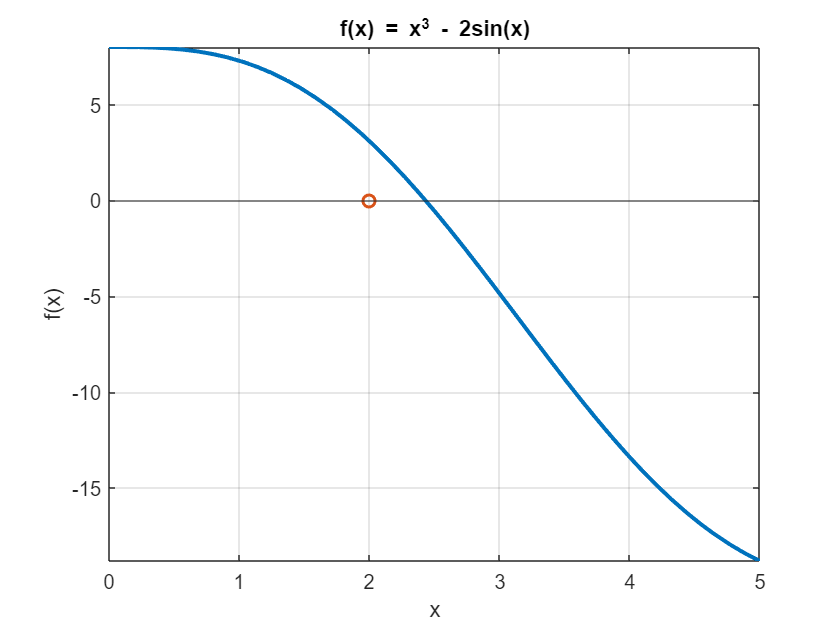

clc, clear, clf
syms x

% Función simbólica f(x)
f = 8 - 4.5*(x - sin(x));

% Gráfica
hold off
fplot(f,'LineWidth', 2)
hold on 
title('f(x) = x^3 - 2sin(x)')
xlabel('x')
ylabel('f(x)')
yline(0)
xlim([0,5])
x_punto = 2;
y_punto = 0;
plot(x_punto, y_punto, 'o', 'LineWidth', 1.5);
grid on

ermax = 0.0001;
xest = 2;
[xs,i] = newtonraphson (f,xest,ermax);
fprintf('Raíz de f(x) por el método de Newton Rapshon : x = %.6f', xs)

Raíz de f(x) por el método de Newton Rapshon : x = 2.430466

fprintf('Número de Iteraciones = %.0f', i);

Número de Iteraciones = 4

solMatlab = vpasolve(f == 0, x);
error_relativo = abs(xs(end) - solMatlab) / abs(solMatlab) * 100;
fprintf('El error entre la solución de Matlab y del Método de Newton Rapshon es: %.8f %%', error_relativo)

El error entre la solución de Matlab y del Método de Newton Rapshon es: 0.00000000 %

## P01_T02_P04 · Método de la secante

### Respuesta:

**a) **Función Adjuntada:  `[xs,i] = RaizSecante(y,xa,xb,ermax)`

**b) **

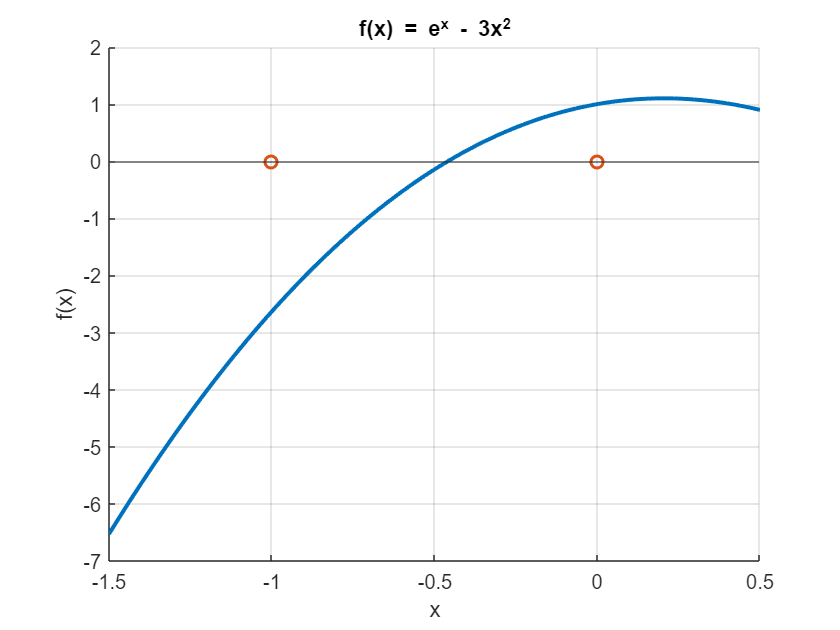

clc, clear, clf
% Función
f = @(x) exp(x)- 3*x.^2;
x = linspace(-1.5, 0.5, 100); % Gráfica entorno a x = -0,5; (-1.5 , 0.5)

% Gráfica
hold on 
yline(0)
y = f(x);
plot(x, y, 'LineWidth', 2);
title('f(x) = e^x - 3x^2')
xlabel('x')
ylabel('f(x)')
x_punto = [-1, 0];
y_punto = [0,0];
plot(x_punto, y_punto, 'o', 'LineWidth', 1.5);

grid on 
hold off

xa = -1;
xb = 0; 
ermax = 0.0001;

[xs, i] = RaizSecante(f, xa, xb, ermax);
fprintf('El método de la Secante ha utilizado %d iteraciones.',i);

El método de la Secante ha utilizado 6 iteraciones.

fprintf('Solucion método de la Secante: %.6f', xs);

Solucion método de la Secante: -0.458962

solMatlab = fzero(f,xa)

solMatlab = -0.4590

error_relativo = abs(xs(end) - solMatlab) / abs(solMatlab) * 100;
fprintf('El error entre la solución de Matlab y de la Secante es: %.6f %%', error_relativo)

El error entre la solución de Matlab y de la Secante es: 0.000009 %

## P01_T02_P05. Método del punto fijo

### Respuesta:

**a)**  Función Adjuntada:  

`    [xs,i] = PuntoFijo(y,xest,ermax) `

**b) **

DIbujamos la función en las proximidades de $x=0$.

clc, clear, clf

% Definimos la función
f = @(x) sin(sqrt(x)) - x;
g = @(x) sin(sqrt(x));
y = @(x) x;

x = linspace(-1, 1, 100);

fs = f(x);
gs = g(x);
ys = y(x);


Para poder trabajar con el Método del Punto Fijo, necesitamos hacer la siguiente transformación:


$$f\left(x\right)=0\to f\left(x\right)=g\left(x\right)-x=0\to g\left(x\right)=x\;$$



$$f\left(x\;\right)=\textrm{sen}\left(\sqrt{x}\right)-x=0\to g\left(x\right)=\textrm{sen}\left(\sqrt{x}\right)=x\;\;$$


Por lo tanto, trabajaermos con $g\left(x\right)=\textrm{sen}\left(\sqrt{x}\right)$ e $y=x\;$

Vamos a dibujar la función $f\left(x\right)$ y las funciones $g\left(x\right)\;e\;y\left(x\right)$

figure('Position', [100, 100, 1400, 400]);

subplot(1, 2, 1);
hold on;
yline(0);
plot(x, fs, 'LineWidth', 2);

title('f(x) = sen(sqrt(x)) - x');
xlabel('x');
ylabel('f(x)');
grid on;
hold off;

subplot(1, 2, 2);
hold on;
plot(x, gs, 'LineWidth', 2);

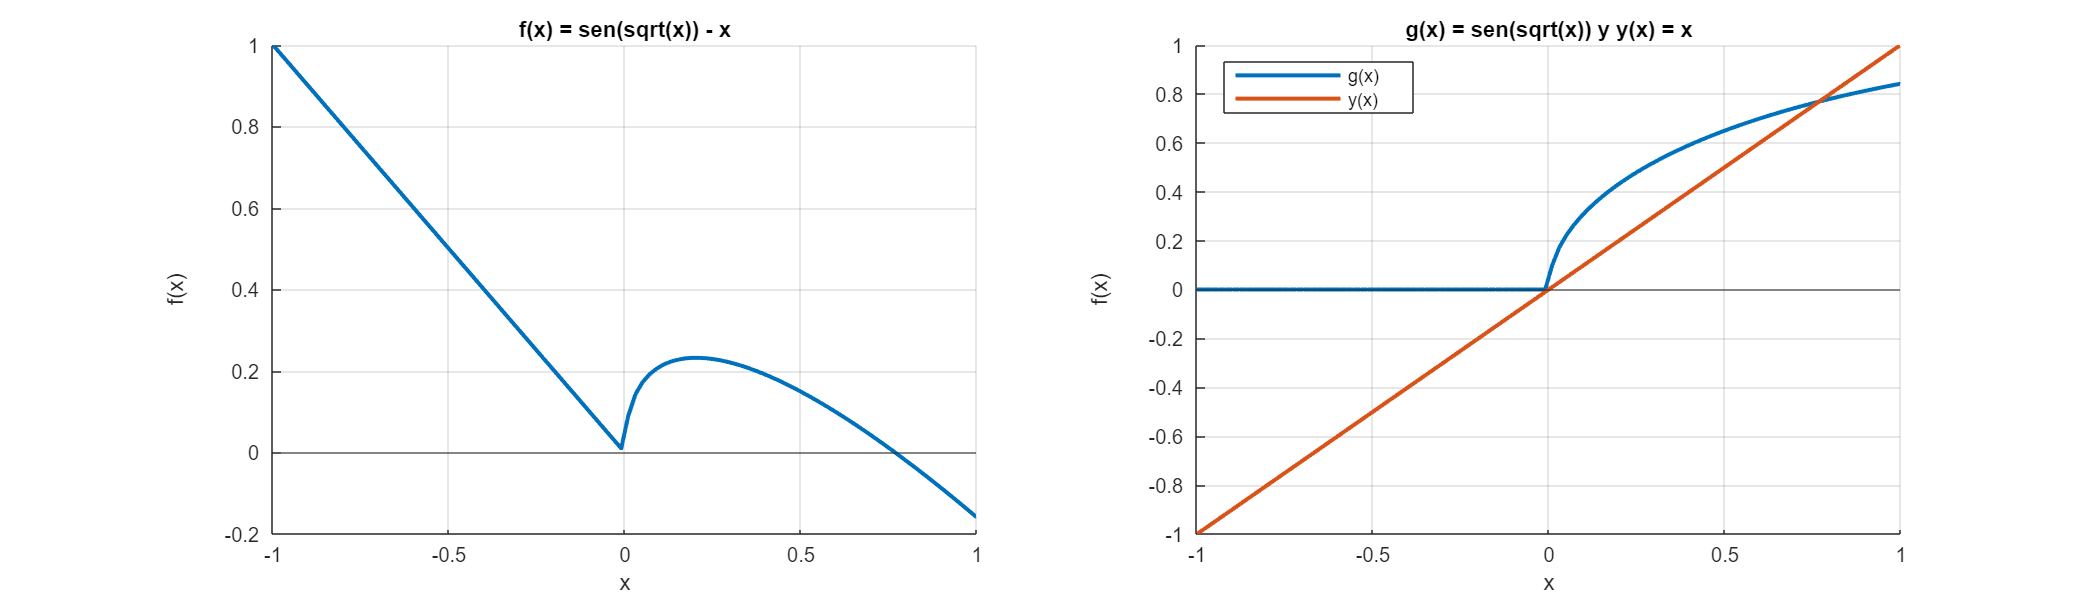

plot(x, ys, 'LineWidth', 2);
title('g(x) = sen(sqrt(x)) y y(x) = x');
xlabel('x');
yline(0);
ylabel('f(x)');
legend('g(x)', 'y(x)','Location', 'northwest');
grid on;
hold off;

Comprobamos el criterio de convergencia ( continuidad de Lipschitz ) :


$$\left|g^{\prime } \left(x\right)\right|<1$$


syms x;
g = sin(sqrt(x));
gPrima = diff(g);
% Evaluamos la derivada en x = 1
x_value = 1;
gPrima1 = subs(gPrima, x, x_value);
fprintf('|gPrima(x)|= %.6f < 1', abs(gPrima1))

|gPrima(x)|= 0.270151 < 1

xest =  1; 
ermax = 0.01 * (1 / 100); 
ymod = @(x) sin(sqrt(x));

[xs,i] = PuntoFijo(ymod,xest,ermax);

T = 9×3 table
    Iteración    Solución    Error Relativo %
    _________    ________    ________________

        1        0.84147            18.84    
        2        0.79397           5.9822    
        3        0.77773           2.0881    
        4        0.77194          0.75011    
        5        0.76985          0.27214    
        6        0.76909         0.099077    
        7        0.76881         0.036118    
        8        0.76871         0.013172    
        9        0.76867        0.0048049    


solMatLab = fzero(f,xest);

% Calcular el error relativo
error_relativo = abs(xs(end) - solMatLab) / abs(solMatLab) * 100;

fprintf('Solucion método del Punto Fijo: %.6f', xs(end))

Solucion método del Punto Fijo: 0.768670

fprintf('El error relativo entre la solución de MATLAB y del punto fijo es: %.6f %%', error_relativo);

El error relativo entre la solución de MATLAB y del punto fijo es: 0.002759 %

## P01_T02_P06. Búsqueda de raíces

### Respuesta

**a)** `Función adjuntada: `

`    [x1, x2] = raizbus(fun, a, b, dx)`

**b) **`Función adjuntada: `

`    x = raices(fun,a,b,dx)`

**c) **`Función adjuntada: `

`    [xs, i] = biseccion (y, a, b, ermax)`

fun = @(x) x.^3 - 10*x.^2 + 5;
p = [1 -10 0 5];
raicesMatlab = roots(p)

raicesMatlab =     9.9495
    0.7346
   -0.6841


Después de obtener las raíces y poder hallar los intervalos de cada raíz, lo siguiente que haremos será acotar los intervalos con el método de **raices** para posteriormente calcular la raíz con el método de **bisección.**

dx = 0.001;
tol = dx * 10e-2;

% Raíz en el intervalo ( 9 , 10 ) 
a1 = 9;
b1 = 10; 
x = raices(fun,a1,b1,dx);
x = rmmissing(x);
fprintf('Intervalo generado por la función raices: (%.4f , %.4f)', x(1), x(end))

Intervalo generado por la función raices: (9.9490 , 9.9500)

[xs1, i1] = biseccion (fun, x(1), x(end), tol);
solMatlab = fzero(fun,b1);

% Raíz en el intervalo ( 0 , 1 ) 
a2 = 0;
b2 = 1; 
x2 = raices(fun,a2,b2,dx);
x2 = rmmissing(x2);
fprintf('Intervalo generado por la función raices: (%.4f , %.4f)', x2(1), x2(end))

Intervalo generado por la función raices: (0.7340 , 0.7350)

[xs2, i2] = biseccion (fun, x2(1), x2(end), tol);
solMatlab2 = fzero(fun,b2);

% Raíz en el intervalo ( -1 , 0 )
a3 = -1;
b3 = 0; 
x3 = raices(fun,a3,b3,dx);
x3 = rmmissing(x3);
fprintf('Intervalo generado por la función raices: (%.4f , %.4f)', x3(1), x3(end))

Intervalo generado por la función raices: (-0.6850 , -0.6840)

[xs3, i3] = biseccion (fun, x3(1), x3(end), tol);
solMatlab3 = fzero(fun,b3);

error_relativo1 = abs(xs1(end) - solMatlab) / abs(solMatlab) * 100;
error_relativo2 = abs(xs2(end) - solMatlab2) / abs(solMatlab2) * 100;
error_relativo3 = abs(xs3(end) - solMatlab3) / abs(solMatlab3) * 100;

error = [error_relativo1, error_relativo2, error_relativo3];
soluciones = [xs1, xs2, xs3];
SolsMatlab = [solMatlab, solMatlab2, solMatlab3];
variables = {[a1 , b1], [a2, b2], [a3 , b3] };

T = table(variables', soluciones',SolsMatlab' , error');
T.Properties.VariableNames = {'IntervaloRaíces','Soluciones Bisección', 'Soluciones Matlab', 'Error Relativo %'}

T = 3×4 table
    IntervaloRaíces    Soluciones Bisección    Soluciones Matlab    Error Relativo %
    _______________    ____________________    _________________    ________________

       {[9 10]}                9.9494                9.9495            0.0005383    
       {[ 0 1]}               0.73456                0.7346            0.0055823    
       {[-1 0]}              -0.68406              -0.68409            0.0046873    
